# Two-dimensional biquadratic basis functions

Construction of the biquadratic two-dimensional basis functions using a tensor product of the one-dimensional quadratic [Lagrange polynomials](https://en.wikipedia.org/wiki/Lagrange_polynomial).

Go to [THIS](matlab:open('./main_Chapter1_BasisFunctions.mlx')) Section in the main driver script *Two-dimensional biquadratic basis functions*

Go to [PREVIOUS](matlab:open('./main_Chapter13_TwoDimensionalBilinearBasisFunctions.mlx')) Section *Two-dimensional bilinear basis functions*

**Author: Dr.-Ing. Andreas Apostolatos**

**Date: 22.12.2022**

## Preamble

vars = "mshQ2";
str = "This mlx-file should be run from parent mlx-file " + ...
    "main_Chapter01_OneDimensionalLinearBasisFunctions.mlx";
for ii = 1:length(vars)
    if ~exist(vars(ii), 'var') 
        error(strcat("Variable ", vars(ii), " is not defined. ", str));
    end
end

## Definition of the biquadratic Lagrange Polynomials

The definition of the biquadratic Lagrange Polynomials is similar to the definition of the bilinear Lagrange polynomials with the only difference that the tensor product contruction rule involves the one-dimensional quadratic Lagrange polynomials.

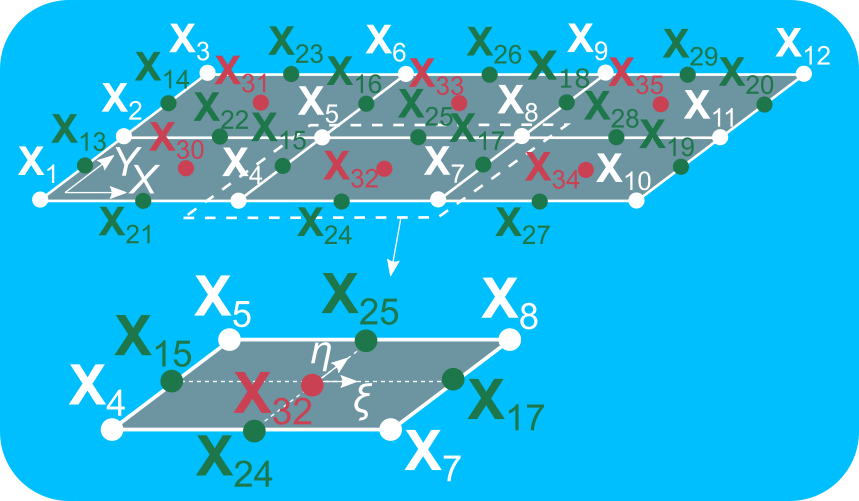

## Set-up of the two-dimensional biquadratic Lagrange polynomials in physical space

The construction of the biquadratic Lagrange polynomials is similar to the construction of the bilinear Lagrange polynomials, namely:


$$l_{i,j}^{\text{Q}_2}(X, Y) = \prod_{1 \le m \le 3, m \neq j} \frac{X - X_m}{X_i - X_m} \prod_{1 \le n \le 3, n \neq j} \frac{Y - Y_n}{Y_i - Y_n}$$


 **Reflect**

Can the latter rule be used to construct elements that have different polynomial degrees along each Cartesian direction?

 **Reflect**

What is the challenge for such elements that attain different polynomial orders along different directions?

### Initialize auxiliary variable

ijQ2 = ["1,1", "1,3", "3,3", "3,1", "1,2", "2,3", "3,2", "2,1", "2,2"];

### Set-up a plot to display all the Lagrange Polynomials associated with the selected element

elQ2 = 3;

### Plot the biaquadratic polynomials on the physical space

plot2dBiquadraticLagrangePolynomialsOnPhysicalSpace ...
    (elQ2, mshQ2, numVertices, l1L2, l2L2, l3L2, ijQ2);

## Two-dimensional biquadratic Lagrange Polynomials

As for the bilinear quadrilateral elements, also for the biquadratic bilinear elements it is chosen the parametric space $(\xi,\eta) \in [-1, 1]^2$. Similar to the parametric space of the quadratic elements, one needs to place additional nodes in the parametric space to allow for interpolating a biquadratic function by means of the high-order interpolatory Lagrange polynomials.

### Set-up of the two-dimensional biquadratic Lagrange Polynomials in the parametric space

syms l11Q2(xi, eta) l13Q2(xi, eta) l33Q2(xi, eta) l31Q2(xi, eta) ...
    l12Q2(xi, eta) l23Q2(xi, eta) l32Q2(xi, eta) l21Q2(xi, eta) l22Q2(xi, eta)
l11Q2(xi, eta) = l1L2(xi, -1, 0, 1)*l1L2(eta, -1, 0, 1);
l13Q2(xi, eta) = l1L2(xi, -1, 0, 1)*l3L2(eta, -1, 0, 1);
l33Q2(xi, eta) = l3L2(xi, -1, 0, 1)*l3L2(eta, -1, 0, 1);
l31Q2(xi, eta) = l3L2(xi, -1, 0, 1)*l1L2(eta, -1, 0, 1);
l12Q2(xi, eta) = l1L2(xi, -1, 0, 1)*l2L2(eta, -1, 0, 1);
l23Q2(xi, eta) = l3L2(xi, -1, 0, 1)*l2L2(eta, -1, 0, 1);
l32Q2(xi, eta) = l2L2(xi, -1, 0, 1)*l1L2(eta, -1, 0, 1);
l21Q2(xi, eta) = l2L2(xi, -1, 0, 1)*l3L2(eta, -1, 0, 1);
l22Q2(xi, eta) = l2L2(xi, -1, 0, 1)*l2L2(eta, -1, 0, 1);
lijQ2 = {l11Q2, l13Q2, l33Q2, l31Q2, l12Q2, l23Q2, l32Q2, l21Q2, l22Q2};

### Visualization of the two-dimensional biquadratic Lagrange Polynomials in the parametric space

t3 = tiledlayout(3, 3);
for ii = 1:numel(lijQ2)
    nexttile
    fsurf(lijQ2{ii}, [-1 1 -1 1], "FaceColor", [217, 218, 219]./255, ...
        "FaceAlpha", 0.5);
    xlabel("\xi")
    ylabel("\eta")
    zlabel(sprintf("l_{%s}", num2str(ijQ2(ii))))
end
title(t3, "Biquadratic Lagrange Polynomials");